mutated=[3,6,9,10,14,15,18,21,28:30]; %+30
unmutated=[1,2,4,5,7,11,13,16,17,19,20,22:26];
nr=[8,27];

patients=[1:11,13:30];

inputFolder='/Figures/03_08/paramAnalysis/';
%inputFolder='/Figures/03_22/paramAnalysis/burger_model/param_char/';
%inputFolder='/Figures/02_20_4_2c/paramAnalysis/burger/';
sheet=1;
%inputFolder='/Figures/'

%outputFolder='/Figures/03_08/paramAnalysis/2004/param_char/';
outputFolder=inputFolder;
inputTableAnalysis="ranksum_kolg_mutation_2.xlsx";
%inputTableParams="paramsAll_extendedWithChars_sepWithChars";
%inputTableParams="paramsAll_extendedWithChars_2004WithChars";
inputTableParams="paramsAll_extendedWithChars_2004WithChars";

alpha=0.05;

analysisResults=readtable(strcat(pwd,inputFolder,inputTableAnalysis));

params=readtable(strcat(pwd,inputFolder,inputTableParams));


row=2;
testResults=analysisResults(row,:);
%Sidak correction
%alpha_mult=1-(1-alpha)^(1/width(testResults));
alpha_mult=alpha;
significant=testResults(:,testResults.Variables<alpha_mult);

significantParamsMutated=params(params.MS=="MUTATED",significant.Properties.VariableNames);
significantParamsUnmutated=params(params.MS=="UNMUTATED",significant.Properties.VariableNames);

params_withoutNR=params(params.MS ~= "NR",:);

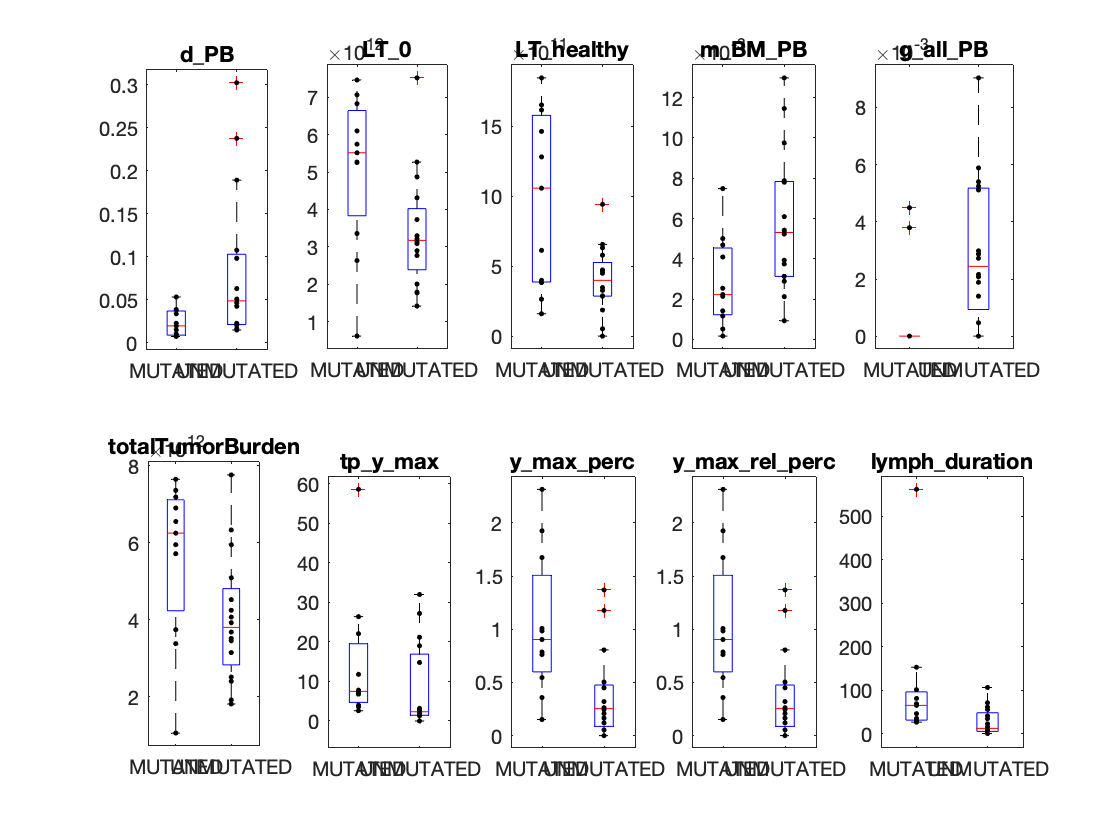

numberParams=size(significant,2);
figure;
counter=0;
for i=[1:numberParams]
    counter=counter+1;
    subplot(2,5,counter);
    %boxplot([significantParamsMutated(:,i).Variables,significantParamsUnmutated(:,i).Variables],'Labels',{'mutated','unmutated'});
    boxplot(params_withoutNR(:,significant.Properties.VariableNames(i)).Variables,params_withoutNR(:,"MS").Variables); hold on;
    ms=params_withoutNR(:,"MS").Variables;
    ds=int8(string(ms)=="MUTATED");

    ds(ds==0)=2;
    scatter(ds,params_withoutNR(:,significant.Properties.VariableNames(i)).Variables,'.k');
%scatter(categorical(params_withoutNR(:,"MS").Variables),params_withoutNR(:,significant.Properties.VariableNames(i)).Variables);
%     plot(ds(ds==1),params_withoutNR(ds==1,significant.Properties.VariableNames(i)).Variables,'*'); hold on;
%     plot(ds(ds==2),params_withoutNR(ds==2,significant.Properties.VariableNames(i)).Variables,'*'); hold on;
    
    title(significant.Properties.VariableNames(i),"Interpreter","none");
end